# ERAU Physical Experiment

Experiment conducted on 11 May 2021

David Olson, 15 May 21

% Start Fresh
close all
clear all
clc

## Extract data from the Data folder

% Build Data Structure
for k = 1 : 61
    
    % Define Distance Strings for the test
    dist_str = 50 : 5 : 350;
    
    % Load in Test Data
    if (dist_str(k) < 100)
        file_name = ['ERAU_SNHT_Test/test_0', num2str(dist_str(k)), '.mat'];
        load(file_name)
    else
        file_name = ['ERAU_SNHT_Test/test_', num2str(dist_str(k)), '.mat'];
        load(file_name)
    end
    
    % Convert Depth Data into xyz
    for kk = 1 : 10
        XYZ(k).frame(kk).xyz = depth2xyz(depth, kk+1, "high");
    end
    
end

% save('XYZ.mat', 'XYZ')

## Plot Resulting Data for Visual Verification

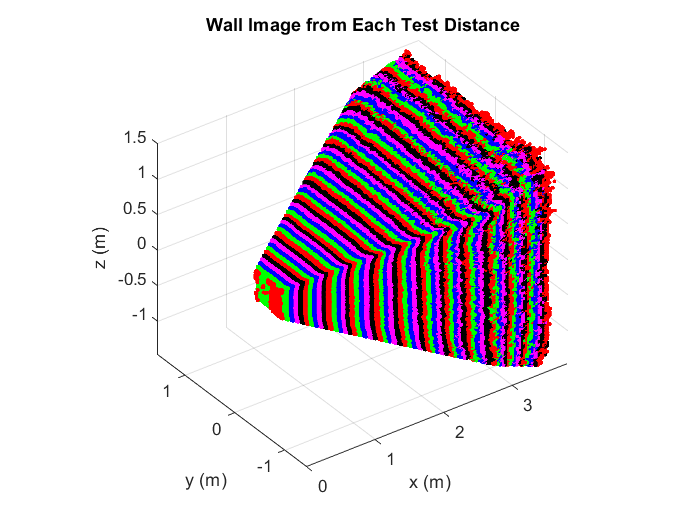

clr_str = ['k', 'r', 'g', 'b', 'm'];

% Plot Data
figure
hold on
f_ind = 9;
for ii = 1 : length(XYZ)
    xyz = XYZ(ii).frame(f_ind).xyz;
    plot3(xyz(1,:), xyz(2,:), xyz(3,:), [clr_str(mod(ii,5)+1), '.']);
end
title('Wall Image from Each Test Distance')
xlabel('x (m)') 
ylabel('y (m)')
zlabel('z (m)')
axis equal
xlim([0 (max(xyz(1,:))+0.1)])
view([-35.952 33.083])
grid
hold on

## Growth of $\sigma_x$

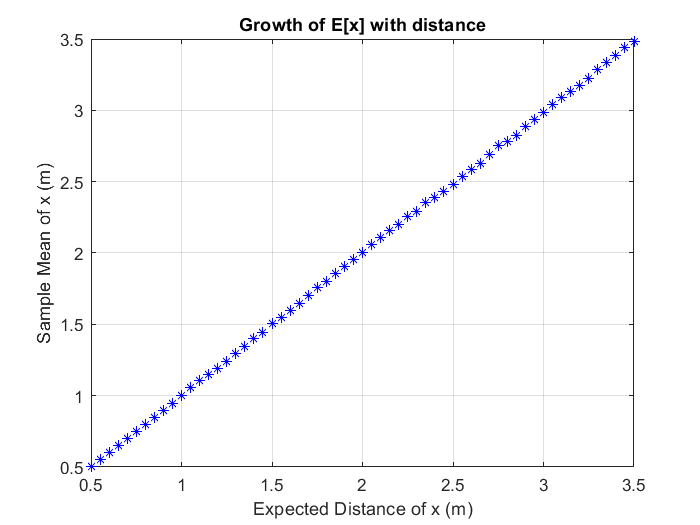

for ii = 1 : length(XYZ)
    xyz = XYZ(ii).frame(f_ind).xyz;
    mean_x(ii) = mean(xyz(1,:));
    sigma_x(ii) = std(xyz(1,:));
end

% Sample Mean of X vs. Desired Distance Measurement
figure
plot(dist_str/100, mean_x, 'b*')
title('Growth of E[x] with distance')
xlabel('Expected Distance of x (m)')
ylabel('Sample Mean of x (m)')
grid on

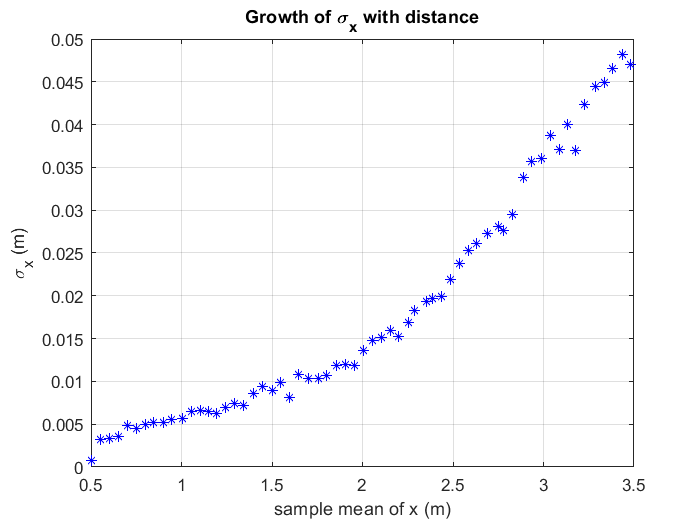


% Sigma of X vs. Sample Mean of X
figure
plot(mean_x, sigma_x, 'b*')
title('Growth of \sigma_x with distance')
xlabel('sample mean of x (m)')
ylabel('\sigma_x (m)')
grid on

## SNHT Expirement

% SNHT Wall Parameters
psi_params = [-45, 0.1, 45] * pi/180;
plot_flag = false;

% Run the SNHT on each wall image
mode_psi = zeros(1, length(XYZ));
psi_var = zeros(1, length(XYZ));

for k = 1 : length(XYZ)
    
    % start timer
    tic
    
    xyz = XYZ(k).frame(f_ind).xyz;
    [mode_psi(k), psi_var(k)] = SNHT_wall_2stage_search(xyz, plot_flag);
    
    % end timer
    fprintf('Run #%d of %d \n', k, length(XYZ))
    toc
    
end

Run #1 of 61 


Elapsed time is 52.473209 seconds.


Run #2 of 61 


Elapsed time is 420.047058 seconds.


Run #3 of 61 


Elapsed time is 482.651162 seconds.


Run #4 of 61 


Elapsed time is 473.837402 seconds.


Run #5 of 61 


Elapsed time is 447.624315 seconds.


Run #6 of 61 


Elapsed time is 409.744808 seconds.


Run #7 of 61 


Elapsed time is 437.649358 seconds.


Run #8 of 61 


Elapsed time is 541.834554 seconds.


Run #9 of 61 


Elapsed time is 528.593843 seconds.


Run #10 of 61 


Elapsed time is 441.860085 seconds.


Run #11 of 61 


Elapsed time is 409.066405 seconds.


Run #12 of 61 


Elapsed time is 432.060520 seconds.


Run #13 of 61 


Elapsed time is 452.373750 seconds.


Run #14 of 61 


Elapsed time is 404.917419 seconds.


Run #15 of 61 


Elapsed time is 411.355520 seconds.


Run #16 of 61 


Elapsed time is 428.171700 seconds.


Run #17 of 61 


Elapsed time is 411.577043 seconds.


Run #18 of 61 


Elapsed time is 424.863705 seconds.


Run #19 of 61 


Elapsed time is 463.361683 seconds.


Run #20 of 61 


Elapsed time is 454.672229 seconds.


Run #21 of 61 


Elapsed time is 402.341951 seconds.


Run #22 of 61 


Elapsed time is 407.763688 seconds.


Run #23 of 61 


Elapsed time is 452.052258 seconds.


Run #24 of 61 


Elapsed time is 466.896629 seconds.


Run #25 of 61 


Elapsed time is 517.371980 seconds.


Run #26 of 61 


Elapsed time is 460.062248 seconds.


Run #27 of 61 


Elapsed time is 509.730476 seconds.


Run #28 of 61 


Elapsed time is 438.810009 seconds.


Run #29 of 61 


Elapsed time is 435.041606 seconds.


Run #30 of 61 


Elapsed time is 448.454497 seconds.


Run #31 of 61 


Elapsed time is 446.869377 seconds.


Run #32 of 61 


Elapsed time is 412.088480 seconds.


Run #33 of 61 


Elapsed time is 410.974996 seconds.


Run #34 of 61 


Elapsed time is 505.434275 seconds.


Run #35 of 61 


Elapsed time is 486.814171 seconds.


Run #36 of 61 


Elapsed time is 466.656997 seconds.


Run #37 of 61 


Elapsed time is 464.304938 seconds.


Run #38 of 61 


Elapsed time is 497.457788 seconds.


Run #39 of 61 


Elapsed time is 448.111117 seconds.


Run #40 of 61 


Elapsed time is 455.899353 seconds.


Run #41 of 61 


Elapsed time is 401.391963 seconds.


Run #42 of 61 


Elapsed time is 403.550442 seconds.


Run #43 of 61 


Elapsed time is 443.154009 seconds.


Run #44 of 61 


Elapsed time is 430.597732 seconds.


Run #45 of 61 


Elapsed time is 479.118793 seconds.


Run #46 of 61 


Elapsed time is 485.555314 seconds.


Run #47 of 61 


Elapsed time is 481.838817 seconds.


Run #48 of 61 


Elapsed time is 493.937011 seconds.


Run #49 of 61 


Elapsed time is 443.962784 seconds.


Run #50 of 61 


Elapsed time is 461.627021 seconds.


Run #51 of 61 


Elapsed time is 395.397793 seconds.


Run #52 of 61 


Elapsed time is 391.767607 seconds.


Run #53 of 61 


Elapsed time is 442.063320 seconds.


Run #54 of 61 


Elapsed time is 434.556482 seconds.


Run #55 of 61 


Elapsed time is 484.627928 seconds.


Run #56 of 61 


Elapsed time is 498.915633 seconds.


Run #57 of 61 


Elapsed time is 488.586655 seconds.


Run #58 of 61 


Elapsed time is 495.243335 seconds.


Run #59 of 61 


Elapsed time is 438.133854 seconds.


Run #60 of 61 


Elapsed time is 442.498949 seconds.


Run #61 of 61 


Elapsed time is 514.599371 seconds.


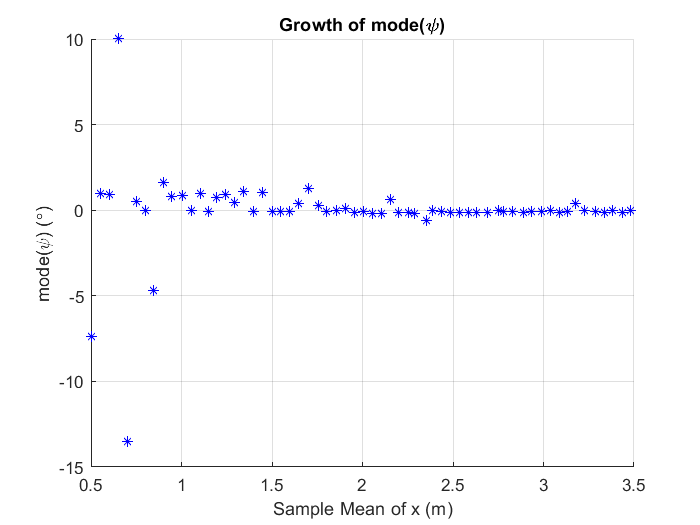


% Plot Mode of Psi
figure
hold on
plot(mean_x, mode_psi * 180/pi, 'b*')
title('Growth of mode(\psi)')
xlabel('Sample Mean of x (m)')
ylabel('mode(\psi) (\circ)')
grid on 
hold off

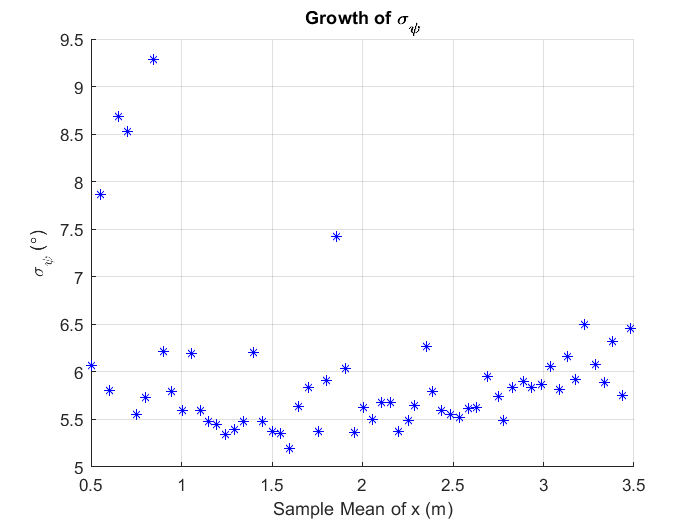


% Plot Sigma of Psi
figure
hold on
plot(mean_x, sqrt(psi_var) * 180/pi, 'b*')
title('Growth of \sigma_\psi')
xlabel('Sample Mean of x (m)')
ylabel('\sigma_\psi (\circ)')
grid on 
hold off